clear all
glucose_M0
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:21)=0.0;
for t=1:21
    varname=genvarname(['media_' int2str((t-1)*100)]);
    clear glucose_field;
    glucose_field=eval(varname);
    for x=1:352
        for y=1:352
            glucose(t)=glucose(t)+glucose_field(x,y);
        end
    end
end


f=plot(0.05*[0:100:2000]/24,glucose(:),'LineWidth',2,'Color','black')

f =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2083 0.4167 0.6250 0.8333 1.0417 1.2500 1.4583 1.6667 1.8750 2.0833 2.2917 2.5000 2.7083 2.9167 3.1250 3.3333 3.5417 3.7500 3.9583 4.1667]
              YData: [0.0372 0.0192 0.0125 0.0077 0.0047 0.0028 0.0016 9.4449e-04 5.5212e-04 3.2254e-04 1.8827e-04 1.0984e-04 6.4057e-05 3.7343e-05 2.1766e-05 1.2684e-05 7.3903e-06 4.3057e-06 2.5083e-06 1.4611e-06 8.5105e-07]

  Show all properties


%xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 5]
             YLim: [0 0.0400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1871 0.1703 0.7179 0.7547]
            Units: 'normalized'

  Show all properties


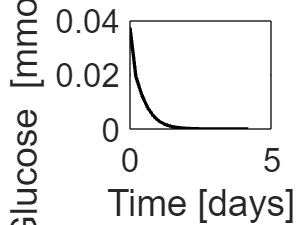

hold on

glucose_M16
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:21)=0.0;
for t=1:21
    varname=genvarname(['media_' int2str((t-1)*100)]);
    clear glucose_field;
    glucose_field=eval(varname);
    for x=1:352
        for y=1:352
            glucose(t)=glucose(t)+glucose_field(x,y);
        end
    end
end

plot(0.05*[0:100:2000]/24,glucose(:),'LineWidth',2,'Color','black')
%xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 5]
             YLim: [0 0.0400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1871 0.1703 0.7179 0.7547]
            Units: 'normalized'

  Show all properties


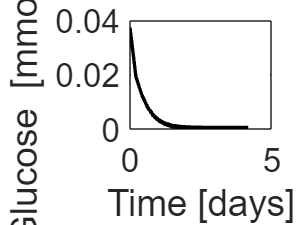

hold on

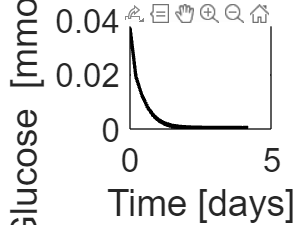

saveas(gcf,['glucose.png'])